# Breaking out Plots from Moment surface Gradient For Scitech 2025 Paper

% First Run Lift Surface Gradients


%% Plot the Colourful MultiSlice
slice_colours = [.5,.5,0; 0,.5,0; 0,0,.5]

slice_colours =     0.5000    0.5000         0
         0    0.5000         0
         0         0    0.5000


% colours
figure
i=0

i = 0

for camber_slope = linspace(0, camberSlope_max, 3)
    i = i+1;
    sliceColor = slice_colours(i,:)

    % compute the camber alpha line
    camber_slice = camber_c + (camber_slope) * (alpha_slice - alpha_c);

    %produce the plots

    % trimetric(ish) view
    surf(rad2deg(Lift_surface_mesh(:,:,1)), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex");
    colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    xlim(rad2deg([-.2,.4])); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    grid on
    slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",.6*sliceColor);
    view([-12.08 47.25]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_l_intercept(1,:), "-", "LineWidth",2, "Color", sliceColor);
    drawnow;
    cb.Label.Position = [3.5, 1.25, 0];
end

Unrecognized function or variable 'camberSlope_max'.




figure
i=0
for camber_slope = linspace(0, camberSlope_max, 3)
    i = i+1;
    sliceColor = slice_colours(i,:)
    % compute the camber alpha line
    camber_slice = camber_c + (camber_slope) * (alpha_slice - alpha_c);
    % side view
    hold on
    surf(rad2deg(Lift_surface_mesh(:,:,1)), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    xlim(rad2deg([-.2,.4])); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    grid on
    %slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",.3*sliceColor);
    view([0,0]);
    % highlight the intersection
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_l_intercept(1,:), "-", "LineWidth",2, "Color", sliceColor);
    drawnow;
    cb.Label.Position = [3.5, 1.25, 0];
end
i=0
figure
for camber_slope = linspace(0, camberSlope_max, 3)
    i = i+1;
    sliceColor = slice_colours(i,:)
    % compute the camber alpha line
    camber_slice = camber_c + (camber_slope) * (alpha_slice - alpha_c);
    % top view
    hold on
    surf(rad2deg(Lift_surface_mesh(:,:,1)), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    xlim(rad2deg([-.2,.4])); ylim([0,1]); zlim([0,2.5]);
    set(gca,"LineWidth", 2);
    hold on
    slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
    view([0,90]);
    % highlight the intersection
    
    [alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
    plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_l_intercept(1,:), "-", "LineWidth",2, "Color", sliceColor);
    grid on
    % update the plot
    drawnow;
    cb.Label.Position = [3.5, 1.25, 0];
end


% the figur for airbitary 3 view

[alpha_slice, C_L_slice] = meshgrid(linspace(min(Lift_surface_mesh(:,:,1),[],"all"), max(Lift_surface_mesh(:,:,1),[],"all"), nSlicePoints), linspace(min(Lift_surface_mesh(:,:,3),[],"all"), max(Lift_surface_mesh(:,:,3),[],"all"), nSlicePoints));


camber_max = max(Lift_surface_mesh(:,:,2),[],"all");
camber_min = min(Lift_surface_mesh(:,:,2),[],"all");
alpha_max = max(Lift_surface_mesh(:,:,1),[],"all");
alpha_min = min(Lift_surface_mesh(:,:,1),[],"all");
camber_slice = camber_max - (camber_max - camber_min) / (alpha_max-alpha_min) * (alpha_slice - alpha_min);

% trimetric(ish) view
figure
surf(rad2deg(Lift_surface_mesh(:,:,1)), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
xlim(rad2deg([-.2,.4])); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
view([-12.08 47.25]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);
cb.Label.Position = [3.5, 1.25, 0];

% side view
figure
surf(rad2deg(Lift_surface_mesh(:,:,1)), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
xlim(rad2deg([-.2,.4])); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);
hold on
%slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",.5, "FaceColor",[0.3,0.3,0.3], "EdgeColor","none");
view([0,0]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);
cb.Label.Position = [3.5, 1.25, 0];

% top view
figure
surf(rad2deg(Lift_surface_mesh(:,:,1)), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $c_l$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
xlim(rad2deg([-.2,.4])); ylim([0,1]); zlim([0,2.5]);
set(gca,"LineWidth", 2);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",1, "EdgeColor","none", "FaceColor",[0.3,0.3,0.3]);
view([0,90]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_l_intercept] = griddata(Lift_surface_mesh(:,:,1), Lift_surface_mesh(:,:,2), Lift_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_l_intercept(1,:), "-k", "LineWidth",2);
cb.Label.Position = [3.5, 1.25, 0];








% First Run Moment Surface Gradients

figure
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on;
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_M_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
view([-12.08 47.25]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);
cb.Label.Position = [3.5, 0, 0];

% side view
figure
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$ $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_M_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
view([0,0]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);
cb.Label.Position = [3.5, 0, 0];

% top view
figure;
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_M_slice, "FaceAlpha",1, "EdgeColor","none", "FaceColor",[.3,.3,.3], "LineWidth",2);
view([0,90]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);
cb.Label.Position = [3.5, 0, 0];


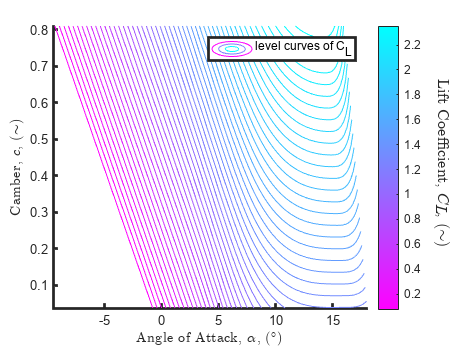

% Contours 
figure; % Lift coefficient gradients
hold on;
contour(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), 50)
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in angle of attack, $C_{L_{\alpha}}$, $(\sim)$", "Interpreter","latex")
legend("level curves of C_L")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);
cb.Label.Position = [3.5, 1.25, 0];

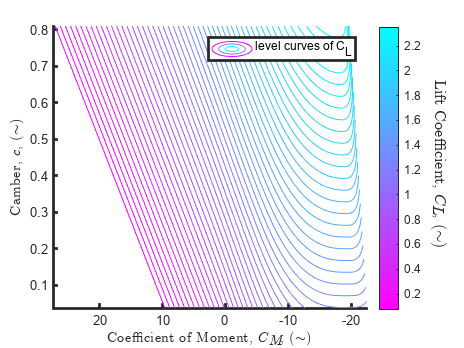


figure; % Moment coefficient gradients
hold on;
%contour(rad2deg(Moment_surface_mesh(alpha_filter_tirm,:,1)), Moment_surface_mesh(alpha_filter_tirm,:,2), Moment_surface_mesh(alpha_filter_tirm,:,4)./Moment_surface_mesh(alpha_filter_tirm,:,3),50)
contour(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), 50);
xlabel("Coefficient of Moment, $C_M$, $(\sim)$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in camber, $C_{L_{camb}}$, $(\sim)$", "Interpreter","latex")
legend("level curves of C_L");
set(gca,'XDir','rev');
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);
cb.Label.Position = [3.5, 1.25, 0];